# Liniowe systemy dynamiczne: reprezentacja ze zmiennymi stanu, sterowalność

Krzysztof Arent

2024

## laboratorium

#### imię i nazwisko studenta: Aleksander Łyskawa i Kacper Karkosz

### Zadanie 1

W teorii sterowania szczególne miejsce zajmuje reprezentacja systemu dynamicznego ze zmiennymi stanu. Własności tej reprezentacji będą przedmiotem tego zadania i kolejnych.

Rozważmy równanie różniczkowe dwóch zmiennych $u$ i $y$,


$$\ddot{y}(t)+a_1 \dot{y}(t) + a_0 y(t) = b_0 u(t) \quad (1)$$


Przyjąć $a_1=3, ~a_0=2, ~b_0=2.$   Wówczas równanie (1) można przekształcić do postaci 


$$\dot{x}(t)=A x(t)+ Bu(t),  \quad (2) \\ y(t)=C x(t)+D u(t), \quad (3)$$
 

gdzie $x_1(t):=y(t), ~x_2(t):=\dot{y}(t)$, $x(t)=$ $x_1(t) \brack x_2(t)$, $A=$$0 \quad1 \brack -a_0 -a_1
$, $B=$ $0 \brack b_0$,   $C=[1 ~ 0]$, $D=0$. 

Zmienne stanu można zdefiniować na wiele innych sposobów. Wtedy macierze A, B, C, D są odpowiednio inne. Ważne jest by systemy (1) i (2,3) były wejściowo-wyjściowo równoważne. Sprawdzić, że faktycznie tak jest, tzn. że dla identycznych pobudzeń w (1) i (2,3) istnieją warunki początkowe dla (1) i dla (2) takie, że wyjścia $y$ w (1) i (3) są identyczne.

Na potrzeby obliczeń numerycznych przyjąć $y(0)=1, ~\dot{y}(0)=1$ oraz $u(t)=\cos(\frac{1}{3}t)$.

*Spostrzeżenie.* Równania (2,3) są szczególną postacią równań w postaci 


$$\dot{x}=f(x,u), ~\quad (4)\\ y=h(x,u), ~\quad (5)$$


które często występują w literaturze z zakresu teorii sterowania nt. nieliniowych układów sterowania.

Powyższe zadanie można zrealizować w sposób następujący:

clear all
close all
% deklaracja zmiennych i funkcji symbolicznych (obiektów klasy sym)
syms t y(t) u(t) s  zmienne_x tau X(t)

% definicje parametrów równania różniczkowego (1)
a1=3;
a0=2;
b0=2;
% implementacja równania różniczkowego (1)
rownanie_1=diff(y(t),t,2)+a1*diff(y(t),t,1)+a0*y(t) == b0*u(t)

$$rownanie\_1 = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+3\,\frac{\partial }{\partial t}y\left(t\right)+2\,y\left(t\right)=2\,u\left(t\right)$$

% specyfikacja warunków początkowych równania różniczkowego (1)
wp=[1,1]' % wp[1]=y(0), wp[2]=y'(0)

wp =      1
     1


% specyfikacja okna czasowego
T=[0,20];
% podstawienie pod u(t) konkretnej funkcji: sin(t/3)
rownanie_1_usin=subs(rownanie_1,{u(t)},{sin(t/3)})

$$rownanie\_1\_usin = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+3\,\frac{\partial }{\partial t}y\left(t\right)+2\,y\left(t\right)=2\,\sin\left(\frac{t}{3}\right)$$

% wyznaczenie rozwiązania równania (1) w postaci analitycznej
rozwiazanie_1 = dsolve(rownanie_1_usin,[y(0)==wp(1),subs(diff(y(t),t,1),{t},{0})==wp(2)]);
y_1(t)=simplify(rozwiazanie_1)

$$y\_1(t) = \frac{18\,{\mathrm{e}}^{-t}}{5}-\frac{80\,{\mathrm{e}}^{-2\,t}}{37}-\frac{9\,\sqrt{370}\,\cos\left(\frac{t}{3}+\mathrm{atan}\left(\frac{17}{9}\right)\right)}{185}$$

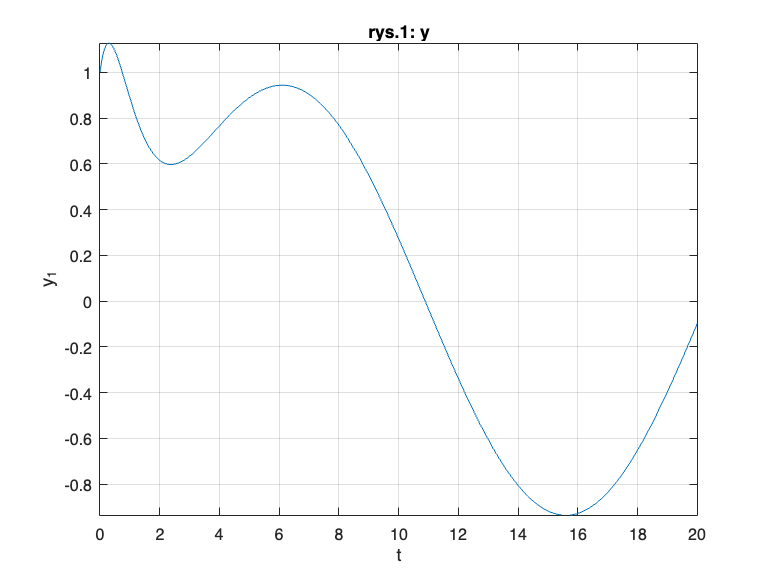

% tworzenie wykresu rozwiązania równania (1)
figure(11)
fplot(y_1(t),T)
grid on, xlabel('t'), ylabel('y_1')
title('rys.1: y')


% wyprowadzanie równań ze zmiennymi stanu (4,5) dla (1)
% przekształcenie równania różniczkowego (1) wyższego rzędu do układu
% równań różniczkowych 1-wszego rzędu
[uklad_rownan, zmienne] = reduceDifferentialOrder(rownanie_1,y(t))

$$uklad\_rownan = \left(\begin{array}{c} \frac{\partial }{\partial t}\mathrm{Dyt}\left(t\right)+3\,\mathrm{Dyt}\left(t\right)-2\,u\left(t\right)+2\,y\left(t\right)\\ \mathrm{Dyt}\left(t\right)-\frac{\partial }{\partial t}y\left(t\right) \end{array}\right)$$

$$zmienne = \left(\begin{array}{c} y\left(t\right)\\ \mathrm{Dyt}\left(t\right) \end{array}\right)$$

% przekształcenie przekształcenie układu równań 1-wzego rzeðu do postaci 
% M*Y(t)'=F(Y(t),t,u(t))
[M,F] = massMatrixForm(uklad_rownan,zmienne)

$$M = \left(\begin{array}{cc} 0 & 1\\ -1 & 0 \end{array}\right)$$

$$F = \left(\begin{array}{c} 2\,u\left(t\right)-3\,\mathrm{Dyt}\left(t\right)-2\,y\left(t\right)\\ -\mathrm{Dyt}\left(t\right) \end{array}\right)$$

% przekształcenie równania M*Y(t)'=F(Y(t),t,u(t)) 
% do postaci x(t)'=f(x(t), u(t))
% (por. równania (4,5)
f = M\F

$$f = \left(\begin{array}{c} \mathrm{Dyt}\left(t\right)\\ 2\,u\left(t\right)-3\,\mathrm{Dyt}\left(t\right)-2\,y\left(t\right) \end{array}\right)$$

for i=1:length(zmienne)
    zmienne_x(i,1)=str2sym(['x',int2str(i),'(t)']);
end
for i=1:length(f)
    f(i)=subs(f(i), zmienne, zmienne_x);
end

% podstawienie pod u(t) w f(x,u) konkretnej funkcji: sin(t/3)
f_u_sin=f;
f_u_sin(2)=subs(f_u_sin(2), u(t), sin(t/3));

% wyznaczanie rozwiązania układu równań x(t)'=f(x(t), sin(1/3*t)), y(t)=x1(t) 
% w postaci numerycznej  
% powyższy układ równań będzie reprezentowany przez obiekt klasy ode
uklad_rownan=ode;
uklad_rownan.ODEFcn=odeFunction(f_u_sin,zmienne_x)

uklad_rownan =   ode with properties:

   Problem definition
               ODEFcn: @(t,in2)[in2(2,:);in2(1,:).*-2.0-in2(2,:).*3.0+sin(t./3.0).*2.0]
          InitialTime: 0
         InitialValue: [0×1 double]

   Solver properties
    AbsoluteTolerance: 1.0000e-06
    RelativeTolerance: 1.0000e-03
               Solver: auto

  Show all properties



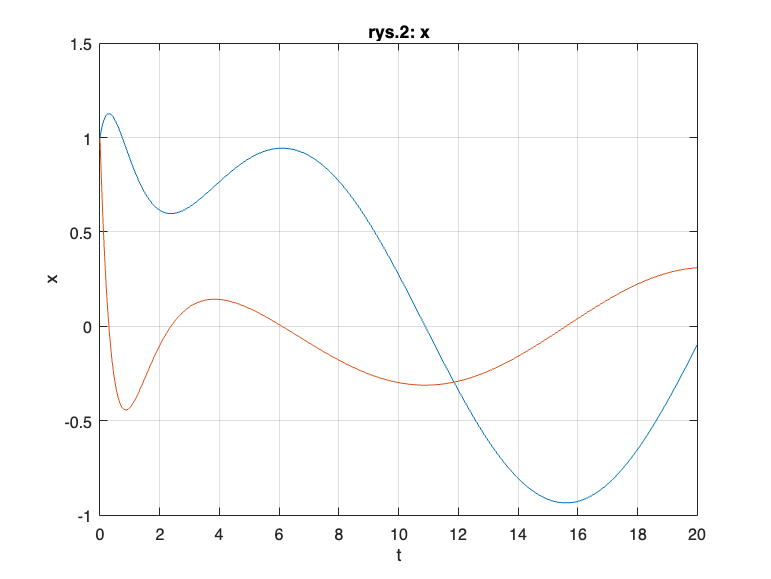

uklad_rownan.InitialTime=0;
uklad_rownan.InitialValue=wp;
rozwiazanie_2=solve(uklad_rownan,0,T(end));
% tworzenie wykresów rozwiązania układu równań (4,5)
figure(12)
plot(rozwiazanie_2.Time, rozwiazanie_2.Solution)
grid on, xlabel('t'), ylabel('x')
title('rys.2: x')

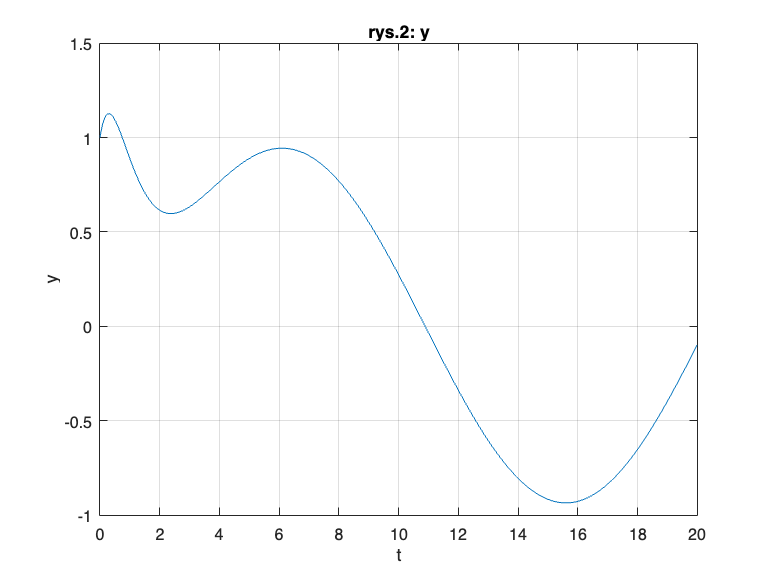

figure(13)
plot(rozwiazanie_2.Time, [1,0]*rozwiazanie_2.Solution)
grid on, xlabel('t'), ylabel('y')
title('rys.2: y')


% wyprowadzanie układu równań (2,3) dla (1)
% przekształcenie równania x(t)'=f(x(t), u(t)) do postaci macierzowej,
% x'(t)=A*x(t)+B*u(t) uzupełnionego o równanie wyjścia y(t)=C*x(t)+D*u(t).
% (por. równania (2,3))
% powyższy układ równań będzie reprezentowany przez obiekt klasy ss z Control System
% Toolbox
A=jacobian(f,zmienne_x)

$$A = \left(\begin{array}{cc} 0 & 1\\ -2 & -3 \end{array}\right)$$

B=jacobian(f,u(t))

$$B = \left(\begin{array}{c} 0\\ 2 \end{array}\right)$$

C=[1,zeros(1,length(zmienne)-1)]

C =      1     0


D=0

D = 0

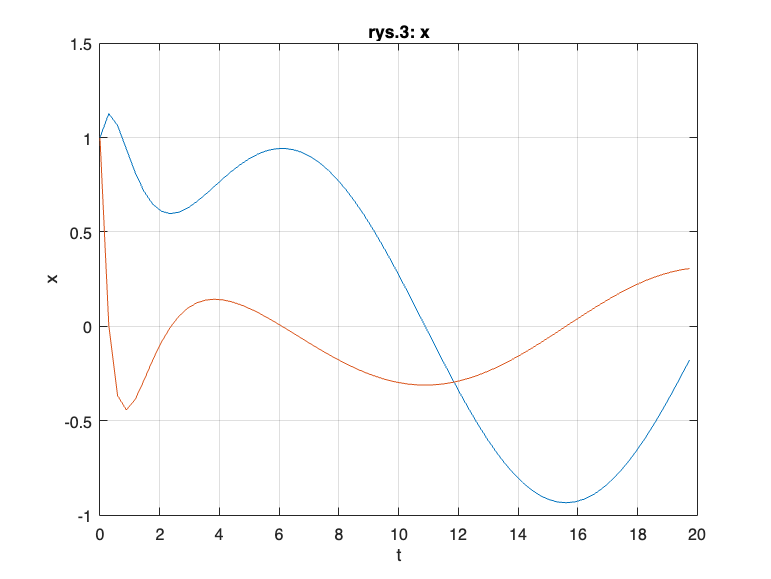

systemDynamiczny=ss(double(A),double(B),C,D);
% konkretne pobudzenie sterujące u(t) ma postać sin(1/3*t)
% reprezentacja powyższego pobudzenia w postaci sekwencji danych może być
% otrzymana m.in. przy użyciu gensig
[u_sin,T_sin] = gensig("sine",2*pi*3,T(end));
T_cos=T_sin;
u_cos=cos(1/3*T_cos);
% rozwiązanie numeryczne układu równań 
% x(t)'=A*x(t)+B*sin(t),
% y(t) =C*x(t)+D*sin(t)
% reprezentowanych przez obiekt klasy ss może być uzyskane przy użyciu
% lsim:
[y_sin, Tout, x_sin]=lsim(systemDynamiczny,u_sin,T_sin, wp);
% tworzenie wykresów rozwiązania układu równań (2,3)
figure(14)
plot(Tout, x_sin)
grid on, xlabel('t'), ylabel('x')
title('rys.3: x')

figure(15) 
plot(Tout, y_sin)
grid on, xlabel('t'), ylabel('y')
title('rys.3: y')

Czy przebiegi na rys.1: y, rys.2: y, rys.3: y oraz na  rys.2: x, rys.3 x są identyczne? Co na podstawie powyższej obserwacji można przypuszczać na temat równoważności wejsciowo/wyjściowej równań różniczkowych analizowanych w powyższym kodzie

**Odpowiedź.** TAK. Poszczególne równania różniczkowe są wejściowo-wyjściowo równoważne. Wynika to z faktu, że równanie różniczkowe dwóch zmiennych zostało przekształcone na równania stanu, a macierze A,B,C i D zostały dobrane tak, aby równoważność wejsciowo/wyjsciowa została zachowana.

Wykonać powyższą analizę dla systemu


$$\dddot{y}+a_2 \ddot{y}(t)+a_1 \dot{y}(t) + a_0 y(t) = b_0 u(t) \quad (6)$$


Przyjąć $a_2=6, a_1=11, ~a_0=6, ~b_0=6$,$y(0)=1, ~\dot{y}(0)=1, ~\ddot{y}(0)=1$ oraz $u(t)=\cos(\frac{1}{3}t)$.  W rozważanym przypadku $x_1(t):=y(t), ~x_2(t):=\dot{y}(t), ~x_3(t) := \ddot{y}(t)$, $x(t)=$ $\left\lbrack \begin{array}{c}
x_1 \left(t\right)\\
x_2 \left(t\right)\\
x_3 \left(t\right)
\end{array}\right\rbrack$, $A=$$\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
{-a}_0  & {-a}_1  & {-a}_2 
\end{array}\right\rbrack$, $B=$ $\left\lbrack \begin{array}{c}
0\\
0\\
b_0 
\end{array}\right\rbrack$,   $C=[1 ~0 ~0]$, $D=0$. 

clear all
close all
% deklaracja zmiennych i funkcji symbolicznych (obiektów klasy sym)
syms t y(t) u(t) s  zmienne_x tau X(t)

% definicje parametrów równania różniczkowego (1)
a1=11;
a0=6;
a2=6;
b0=6;
% implementacja równania różniczkowego (1)
rownanie_1=diff(y(t),t,3)+a2*diff(y(t),t,2)+a1*diff(y(t),t,1)+a0*y(t) == b0*u(t)

$$rownanie\_1 = \frac{\partial^{3}}{\partial t^{3}}y\left(t\right)+6\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+11\,\frac{\partial }{\partial t}y\left(t\right)+6\,y\left(t\right)=6\,u\left(t\right)$$

% specyfikacja warunków początkowych równania różniczkowego (1)
wp=[1,1,1]' % wp[1]=y(0), wp[2]=y'(0)

wp =      1
     1
     1


% specyfikacja okna czasowego
T=[0,20];
% podstawienie pod u(t) konkretnej funkcji: sin(t/3)
rownanie_1_usin=subs(rownanie_1,{u(t)},{cos(t/3)})

$$rownanie\_1\_usin = \frac{\partial^{3}}{\partial t^{3}}y\left(t\right)+6\,\frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+11\,\frac{\partial }{\partial t}y\left(t\right)+6\,y\left(t\right)=6\,\cos\left(\frac{t}{3}\right)$$

% wyznaczenie rozwiązania równania (1) w postaci analitycznej
rozwiazanie_1 = dsolve(rownanie_1_usin,[y(0)==wp(1),subs(diff(y(t),t,1),{t},{0})==wp(2), subs(diff(y(t),t,2),{t},{0})==wp(3)]);
y_1(t)=simplify(rozwiazanie_1)

$$y\_1(t) = \frac{33\,{\mathrm{e}}^{-t}}{10}-\frac{188\,{\mathrm{e}}^{-2\,t}}{37}+\frac{165\,{\mathrm{e}}^{-3\,t}}{82}+\frac{81\,\sqrt{7585}\,\cos\left(\frac{t}{3}-\mathrm{atan}\left(\frac{49}{72}\right)\right)}{7585}$$

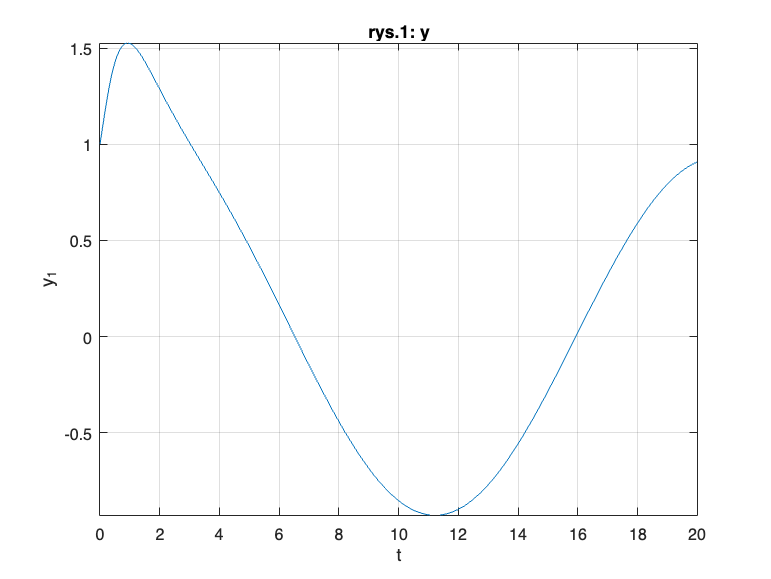

% tworzenie wykresu rozwiązania równania (1)
figure(11)
fplot(y_1(t),T)
grid on, xlabel('t'), ylabel('y_1')
title('rys.1: y')


% wyprowadzanie równań ze zmiennymi stanu (4,5) dla (1)
% przekształcenie równania różniczkowego (1) wyższego rzędu do układu
% równań różniczkowych 1-wszego rzędu
[uklad_rownan, zmienne] = reduceDifferentialOrder(rownanie_1,y(t))

$$uklad\_rownan = \left(\begin{array}{c} \frac{\partial }{\partial t}\mathrm{Dytt}\left(t\right)+11\,\mathrm{Dyt}\left(t\right)+6\,\mathrm{Dytt}\left(t\right)-6\,u\left(t\right)+6\,y\left(t\right)\\ \mathrm{Dyt}\left(t\right)-\frac{\partial }{\partial t}y\left(t\right)\\ \mathrm{Dytt}\left(t\right)-\frac{\partial }{\partial t}\mathrm{Dyt}\left(t\right) \end{array}\right)$$

$$zmienne = \left(\begin{array}{c} y\left(t\right)\\ \mathrm{Dyt}\left(t\right)\\ \mathrm{Dytt}\left(t\right) \end{array}\right)$$

% przekształcenie przekształcenie układu równań 1-wzego rzeðu do postaci 
% M*Y(t)'=F(Y(t),t,u(t))
[M,F] = massMatrixForm(uklad_rownan,zmienne)

$$M = \left(\begin{array}{ccc} 0 & 0 & 1\\ -1 & 0 & 0\\ 0 & -1 & 0 \end{array}\right)$$

$$F = \left(\begin{array}{c} 6\,u\left(t\right)-6\,\mathrm{Dytt}\left(t\right)-11\,\mathrm{Dyt}\left(t\right)-6\,y\left(t\right)\\ -\mathrm{Dyt}\left(t\right)\\ -\mathrm{Dytt}\left(t\right) \end{array}\right)$$

% przekształcenie równania M*Y(t)'=F(Y(t),t,u(t)) 
% do postaci x(t)'=f(x(t), u(t))
% (por. równania (4,5)
f = M\F

$$f = \left(\begin{array}{c} \mathrm{Dyt}\left(t\right)\\ \mathrm{Dytt}\left(t\right)\\ 6\,u\left(t\right)-6\,\mathrm{Dytt}\left(t\right)-11\,\mathrm{Dyt}\left(t\right)-6\,y\left(t\right) \end{array}\right)$$

for i=1:length(zmienne)
    zmienne_x(i,1)=str2sym(['x',int2str(i),'(t)']);
end
for i=1:length(f)
    f(i)=subs(f(i), zmienne, zmienne_x);
end

% podstawienie pod u(t) w f(x,u) konkretnej funkcji: sin(t/3)
f_u_sin=f;
f_u_sin(3)=subs(f_u_sin(3), u(t), cos(t/3));

% wyznaczanie rozwiązania układu równań x(t)'=f(x(t), sin(1/3*t)), y(t)=x1(t) 
% w postaci numerycznej  
% powyższy układ równań będzie reprezentowany przez obiekt klasy ode
uklad_rownan=ode;
uklad_rownan.ODEFcn=odeFunction(f_u_sin,zmienne_x)

uklad_rownan =   ode with properties:

   Problem definition
               ODEFcn: @(t,in2)[in2(2,:);in2(3,:);in2(1,:).*-6.0-in2(2,:).*1.1e+1-in2(3,:).*6.0+cos(t./3.0).*6.0]
          InitialTime: 0
         InitialValue: [0×1 double]

   Solver properties
    AbsoluteTolerance: 1.0000e-06
    RelativeTolerance: 1.0000e-03
               Solver: auto

  Show all properties



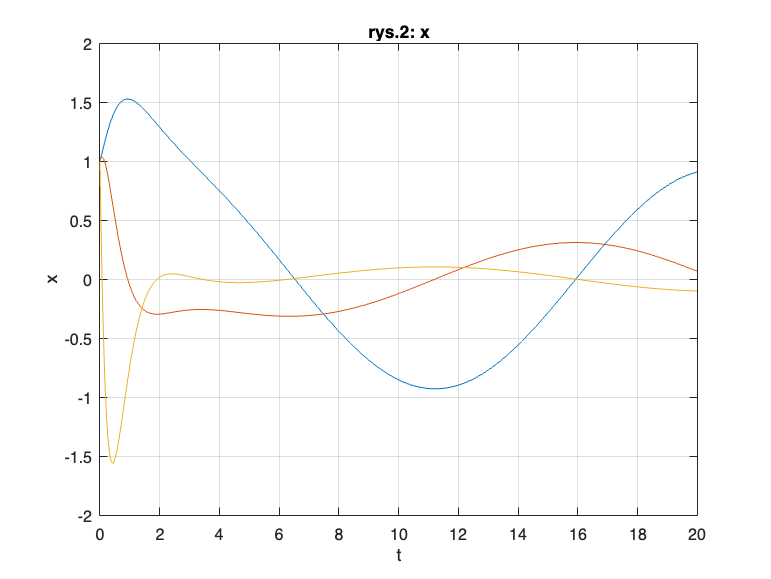

uklad_rownan.InitialTime=0;
uklad_rownan.InitialValue=wp;
rozwiazanie_2=solve(uklad_rownan,0,T(end));
% tworzenie wykresów rozwiązania układu równań (4,5)
figure(12)
plot(rozwiazanie_2.Time, rozwiazanie_2.Solution)
grid on, xlabel('t'), ylabel('x')
title('rys.2: x')

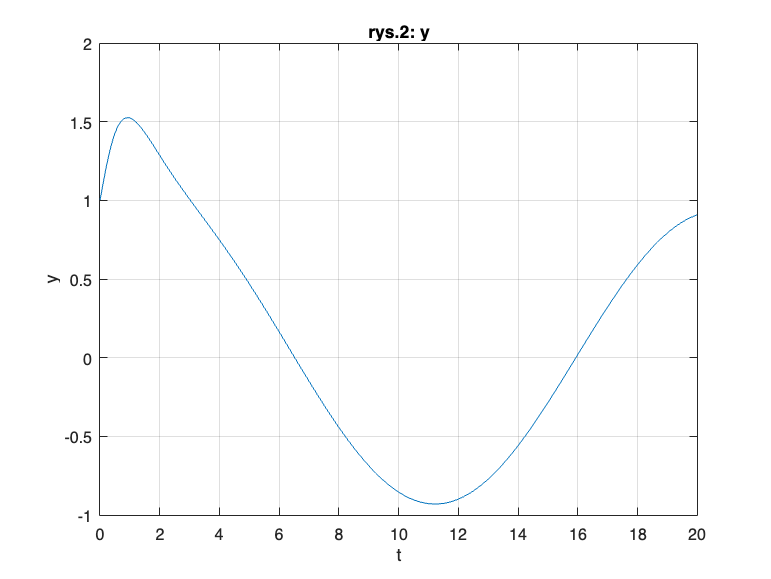

figure(13)
plot(rozwiazanie_2.Time, [1,0,0]*rozwiazanie_2.Solution)
grid on, xlabel('t'), ylabel('y')
title('rys.2: y')


% wyprowadzanie układu równań (2,3) dla (1)
% przekształcenie równania x(t)'=f(x(t), u(t)) do postaci macierzowej,
% x'(t)=A*x(t)+B*u(t) uzupełnionego o równanie wyjścia y(t)=C*x(t)+D*u(t).
% (por. równania (2,3))
% powyższy układ równań będzie reprezentowany przez obiekt klasy ss z Control System
% Toolbox
A=jacobian(f,zmienne_x)

$$A = \left(\begin{array}{ccc} 0 & 1 & 0\\ 0 & 0 & 1\\ -6 & -11 & -6 \end{array}\right)$$

B=jacobian(f,u(t))

$$B = \left(\begin{array}{c} 0\\ 0\\ 6 \end{array}\right)$$

C=[1,zeros(1,length(zmienne)-1)]

C =      1     0     0


D=0

D = 0

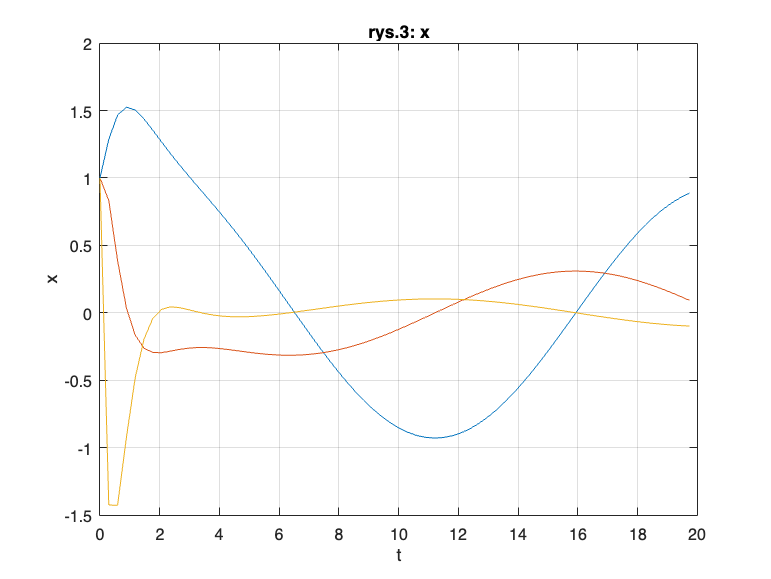

systemDynamiczny=ss(double(A),double(B),C,D);
% konkretne pobudzenie sterujące u(t) ma postać sin(1/3*t)
% reprezentacja powyższego pobudzenia w postaci sekwencji danych może być
% otrzymana m.in. przy użyciu gensig
[u_sin,T_sin] = gensig("sine",2*pi*3,T(end));
T_cos=T_sin;
u_cos=cos(1/3*T_cos);
% rozwiązanie numeryczne układu równań 
% x(t)'=A*x(t)+B*sin(t),
% y(t) =C*x(t)+D*sin(t)
% reprezentowanych przez obiekt klasy ss może być uzyskane przy użyciu
% lsim:
[y_sin, Tout, x_sin]=lsim(systemDynamiczny,u_cos,T_cos, wp);
% tworzenie wykresów rozwiązania układu równań (2,3)
figure(14)
plot(Tout, x_sin)
grid on, xlabel('t'), ylabel('x')
title('rys.3: x')

figure(15) 
plot(Tout, y_sin)
grid on, xlabel('t'), ylabel('y')
title('rys.3: y')

Udzielić odpowiedzi na analogiczne pytanie jak dla wcześniejszego przypadku nt. równoważności wejściowo-wyjściowej układów równań analizowanych w powyższym kodzie.

**Odpowiedź.** TAK. Poszczególne równania różniczkowe są wejściowo-wyjściowo równoważne.

### Zadanie 2

Rozważmy układ równań (2,3). Można pokazać, że rozwiązanie (2) może przyjąć następującą postać:


$$x(t)=e^{A t} x(0)+\int_0^t e^{A(t-\tau)} B u(\tau) d\tau. \quad (7)$$


Wyznaczyć $e^{A t}$ dla (2). Sprawdzić, że 

 
$$e^{A \cdot 0}=I, \quad (8) \\ 
\frac{d}{dt}e^{A t} = A e^{A t} \quad (9) $$


Narysować wykres $x(t)$ z (7) dla $x(0)=[1 ~1]^T$. 

clear all
close all
% deklaracja zmiennych i funkcji symbolicznych (obiektów klasy sym)
syms t tau u(t) X(t) expAt(t)

% definicje parametrów równania różniczkowego (2)
a1=3;
a0=2;
b0=2;
A=[0 1; -a0 -a1]

A =      0     1
    -2    -3


B=[0;b0]

B =      0
     2


% wyznaczanie e^{A*t}
expAt(t)=expm(A*t)

$$expAt(t) = \left(\begin{array}{cc} 2\,{\mathrm{e}}^{-t}-{\mathrm{e}}^{-2\,t} & {\mathrm{e}}^{-t}-{\mathrm{e}}^{-2\,t}\\ 2\,{\mathrm{e}}^{-2\,t}-2\,{\mathrm{e}}^{-t} & 2\,{\mathrm{e}}^{-2\,t}-{\mathrm{e}}^{-t} \end{array}\right)$$

% badanie, że e^{A*t} spełnia własności macierzy podstawowej
if all(all(expAt(0) - eye(size(A,1)) == 0))
    disp(':)');
else
    disp(':(');
end

:)


if all(all(simplify(diff(expAt(t),t,1)-A*expAt(t))==0))
    disp(':)');
else 
    disp(':(');
end

:)


% badanie rozwiązania (7) równania różniczkowego (2)
wp=[1;1];
u(t)=sin(1/3*t);
X(t)=expm(A*t)*wp+int(expm(A*(t-tau))*B*u(tau),tau,0,t)

$$X(t) = \left(\begin{array}{c} \frac{18\,{\mathrm{e}}^{-t}}{5}-\frac{81\,\cos\left(\frac{t}{3}\right)}{185}-\frac{80\,{\mathrm{e}}^{-2\,t}}{37}+\frac{153\,\sin\left(\frac{t}{3}\right)}{185}\\ \frac{51\,\cos\left(\frac{t}{3}\right)}{185}-\frac{18\,{\mathrm{e}}^{-t}}{5}+\frac{160\,{\mathrm{e}}^{-2\,t}}{37}+\frac{27\,\sin\left(\frac{t}{3}\right)}{185} \end{array}\right)$$

x = matlabFunction(X(t))

x = function_handle with value:
    @(t)[cos(t./3.0).*(-8.1e+1./1.85e+2)+exp(-t).*(1.8e+1./5.0)-exp(t.*-2.0).*(8.0e+1./3.7e+1)+sin(t./3.0).*(1.53e+2./1.85e+2);cos(t./3.0).*(5.1e+1./1.85e+2)-exp(-t).*(1.8e+1./5.0)+exp(t.*-2.0).*(1.6e+2./3.7e+1)+sin(t./3.0).*(2.7e+1./1.85e+2)]


T=0:0.1:20;
% tworzenie wykresu dla x(t) z (7)
figure(21)
plot(T,x(T))
grid on, xlabel('t'), ylabel('x')
title('rys.4: x')

Porównać uzyskany wykres $x(t)$ na rys.4: x z wykresem $x(t)$ dla systemu (2) z Zadania 1 na rys.2: x i rys.3 x. Czy wykresy są identyczne? Czy możemy zatem przypuszczać, że (7) jest rozwiązaniem (2)?

**Odpowiedź.** TAK, ponieważ wykres x(t) na rys.4 jest identyczny jak wykresy z zadania 1 na rysunkach rys.2 i rys.3., więc (7) wygląda na rozwiązanie równań stanu w postaci macierzowej (2)

Wykonać powyższą analizę dla systemu (6). Przyjąć $a_2=6, a_1=11, ~a_0=6, ~b_0=6$,$y(0)=1, ~\dot{y}(0)=1, ~\ddot{y}(0)=1$ oraz $u(t)=\cos(\frac{1}{3}t)$.  

clear all
close all
% deklaracja zmiennych i funkcji symbolicznych (obiektów klasy sym)
syms t tau u(t) X(t) expAt(t)

% definicje parametrów równania różniczkowego (2)
a1=11;
a2=6;
a0=6;
b0=6;
A=[0 1 0; 0 0 1; -a0 -a1 -a2]

A =      0     1     0
     0     0     1
    -6   -11    -6


B=[0;0;b0]

B =      0
     0
     6



% wyznaczanie e^{A*t}
expAt(t)=expm(A*t)

$$expAt(t) = \begin{array}{l} \left(\begin{array}{ccc} 3\,{\mathrm{e}}^{-t}-3\,{\mathrm{e}}^{-2\,t}+{\mathrm{e}}^{-3\,t} & \sigma_{1}-\sigma_{3}+\frac{\sigma_{4}}{2} & \frac{{\mathrm{e}}^{-t}}{2}-{\mathrm{e}}^{-2\,t}+\frac{{\mathrm{e}}^{-3\,t}}{2}\\ 6\,{\mathrm{e}}^{-2\,t}-3\,{\mathrm{e}}^{-t}-\sigma_{4} & 8\,{\mathrm{e}}^{-2\,t}-\sigma_{1}-\frac{\sigma_{2}}{2} & 2\,{\mathrm{e}}^{-2\,t}-\frac{{\mathrm{e}}^{-t}}{2}-\frac{\sigma_{4}}{2}\\ 3\,{\mathrm{e}}^{-t}-12\,{\mathrm{e}}^{-2\,t}+\sigma_{2} & \sigma_{1}-16\,{\mathrm{e}}^{-2\,t}+\frac{27\,{\mathrm{e}}^{-3\,t}}{2} & \frac{{\mathrm{e}}^{-t}}{2}-\sigma_{3}+\frac{\sigma_{2}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{5\,{\mathrm{e}}^{-t}}{2}\\ \sigma_{2}=9\,{\mathrm{e}}^{-3\,t}\\ \sigma_{3}=4\,{\mathrm{e}}^{-2\,t}\\ \sigma_{4}=3\,{\mathrm{e}}^{-3\,t} \end{array}$$

% badanie, że e^{A*t} spełnia własności macierzy podstawowej
if all(all(expAt(0) - eye(size(A,1)) == 0))
    disp(':)');
else
    disp(':(');
end

:)


if all(all(simplify(diff(expAt(t),t,1)-A*expAt(t))==0))
    disp(':)');
else 
    disp(':(');
end

:)


% badanie rozwiązania (7) równania różniczkowego (2)
wp=[1;1;1];
u(t)=cos(1/3*t);
X(t)=expm(A*t)*wp+int(expm(A*(t-tau))*B*u(tau),tau,0,t)

$$X(t) = \begin{array}{l} \left(\begin{array}{c} \frac{5832\,\cos\left(\frac{t}{3}\right)}{7585}+\sigma_{1}-\frac{188\,{\mathrm{e}}^{-2\,t}}{37}+\frac{165\,{\mathrm{e}}^{-3\,t}}{82}+\frac{3969\,\sin\left(\frac{t}{3}\right)}{7585}\\ \frac{1323\,\cos\left(\frac{t}{3}\right)}{7585}-\sigma_{1}+\frac{376\,{\mathrm{e}}^{-2\,t}}{37}-\frac{495\,{\mathrm{e}}^{-3\,t}}{82}-\frac{1944\,\sin\left(\frac{t}{3}\right)}{7585}\\ \sigma_{1}-\frac{648\,\cos\left(\frac{t}{3}\right)}{7585}-\frac{752\,{\mathrm{e}}^{-2\,t}}{37}+\frac{1485\,{\mathrm{e}}^{-3\,t}}{82}-\frac{441\,\sin\left(\frac{t}{3}\right)}{7585} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{33\,{\mathrm{e}}^{-t}}{10} \end{array}$$

x = matlabFunction(X(t))

x = function_handle with value:
    @(t)[cos(t./3.0).*7.688859591298616e-1+exp(-t).*(3.3e+1./1.0e+1)-exp(t.*-2.0).*(1.88e+2./3.7e+1)+exp(t.*-3.0).*(1.65e+2./8.2e+1)+sin(t./3.0).*5.232696110744891e-1;cos(t./3.0).*1.744232036914964e-1-exp(-t).*(3.3e+1./1.0e+1)+exp(t.*-2.0).*(3.76e+2./3.7e+1)-exp(t.*-3.0).*(4.95e+2./8.2e+1)-sin(t./3.0).*2.562953197099539e-1;cos(t./3.0).*(-8.543177323665129e-2)+exp(-t).*(3.3e+1./1.0e+1)-exp(t.*-2.0).*(7.52e+2./3.7e+1)+exp(t.*-3.0).*1.810975609756098e+1-sin(t./3.0).*5.814106789716546e-2]


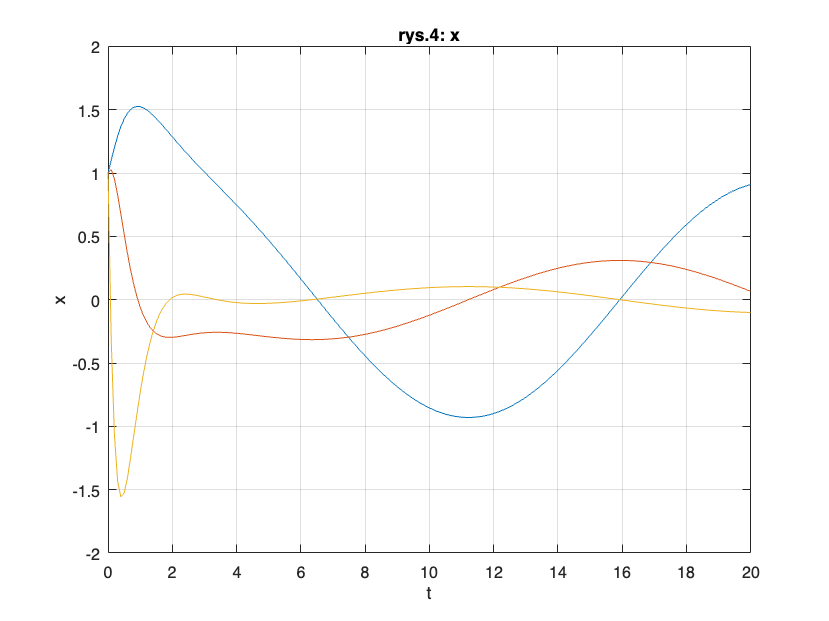

T=0:0.1:20;
% tworzenie wykresu dla x(t) z (7)
figure(21)
plot(T,x(T))
grid on, xlabel('t'), ylabel('x')
title('rys.4: x')

Czy na gruncie uzyskanych wyników dalej możemy przypuszczać, że (7) jest rozwiązaniem (2)?

**Odpowiedź.** TAK

## Zadanie 3

Rozważmy reprezentację liniowego systemu sterowania ze zmiennymi stanu (2). Sterowanie $u(t)$, które przemieszcza ten system ze stanu $x_0$ do stanu $x_1$ w czasie $t_1$ może mieć następującą postać:


$$u(t)=B^T e^{-A^T t} W_{t_1}^{-1} (e^{-A t_1} x_1-x_0), \quad (10) \\
W_{t_1}=\int_0^{t_1}  e^{-A \tau } B B^T e^{-A ^T\tau } d \tau \quad (11)$$


$W_{t_1}$w (11) jest nazywane gramianem sterowalności. 

Sprawdzić, że sterowanie (9,10) jest w stanie przemieścić stan systemu (2) ze stanu $x_0=$ $1 \brack 1$ do stanu $x_1=$ $-1 \brack 2$ w czasie $t_1=10\mathrm{ [s]}$. $A=$$0 \quad1 \brack -a_0 -a_1
$, $B=$ $0 \brack b_0$.  Przyjąć $a_1=3, ~a_0=2, ~b_0=2.$   Powyższe zadanie można zrealizować w sposób następujący:

clear all
close all
% deklaracja zmiennych i funkcji symbolicznych (obiektów klasy sym)
syms t u(t) tau X(t) W

% definicje parametrów równania różniczkowego (2)
a1=3;
a0=2;
b0=2;
A=[0 1; -a0 -a1]

A =      0     1
    -2    -3


B=[0;b0]

B =      0
     2


C=[1,zeros(1,size(A,1)-1)]

C =      1     0


D=0

D = 0

% deklaracje parametrów specyfikujących zadanie sterowania
t1=10

t1 = 10

x0=[1;1];
x1=[-1;2];
% implementacja gramianu sterowalności (11)
W=int(expm(-A*tau)*B*B'*expm(-A'*tau),tau,0,t1)

$$W = \left(\begin{array}{cc} {\left({\mathrm{e}}^{10}-1\right)}^{3}\,\left({\mathrm{e}}^{10}+\frac{1}{3}\right) & -2\,{\mathrm{e}}^{20}\,{\left({\mathrm{e}}^{10}-1\right)}^{2}\\ -2\,{\mathrm{e}}^{20}\,{\left({\mathrm{e}}^{10}-1\right)}^{2} & 2\,{\mathrm{e}}^{20}-\frac{16\,{\mathrm{e}}^{30}}{3}+4\,{\mathrm{e}}^{40}-\frac{2}{3} \end{array}\right)$$

% implementacja algorytmu sterowania (10)
u(t)=B'*expm(-A'*t)*inv(W)*(expm(-A*t1)*x1-x0)

$$u(t) = \begin{array}{l} -\frac{24419163887549121\,\sigma_{3}\,\left({\mathrm{e}}^{10}-2\,{\mathrm{e}}^{20}+6\,{\mathrm{e}}^{30}+1\right)}{16777216\,\left({\mathrm{e}}^{10}-8\,{\mathrm{e}}^{20}+8\,{\mathrm{e}}^{30}-{\mathrm{e}}^{40}-{\mathrm{e}}^{50}+1\right)}-\frac{73257491436155037\,{\mathrm{e}}^{20}\,\sigma_{3}}{8388608\,\sigma_{1}}-\frac{73257491662647363\,{\mathrm{e}}^{20}\,\sigma_{2}}{16777216\,\sigma_{1}}-\frac{24419163812051679\,\left(3\,{\mathrm{e}}^{10}+1\right)\,\sigma_{2}}{16777216\,\left(3\,{\mathrm{e}}^{10}-3\,{\mathrm{e}}^{20}-{\mathrm{e}}^{30}+1\right)}\\ \mathrm{where}\\ \sigma_{1}=2\,{\mathrm{e}}^{10}-6\,{\mathrm{e}}^{20}+2\,{\mathrm{e}}^{30}+{\mathrm{e}}^{40}+1\\ \sigma_{2}=4\,{\mathrm{e}}^{2\,t}-2\,{\mathrm{e}}^{t}\\ \sigma_{3}=2\,{\mathrm{e}}^{2\,t}-2\,{\mathrm{e}}^{t} \end{array}$$

% implementacja rozwiązana (7) równania róźniczkowego (2) 
% dla u w postaci (10)
X(t)=expm(A*t)*x0+int(expm(A*(t-tau))*B*u(tau),tau,0,t)

x = matlabFunction(X(t))

x = function_handle with value:
    @(t)[exp(-t).*3.0-exp(t.*-2.0).*2.0+(sinh(t).*5.821982338917656e+9)./(exp(1.0e+1).*3.0-exp(2.0e+1).*3.0-exp(3.0e+1)+1.0)+(sinh(t).*5.821982356917649e+9)./(exp(1.0e+1)-exp(2.0e+1).*8.0+exp(3.0e+1).*8.0-exp(4.0e+1)-exp(5.0e+1)+1.0)+((exp(t.*-2.0)./3.0-exp(t)./3.0).*5.821982338917656e+9)./(exp(1.0e+1).*3.0-exp(2.0e+1).*3.0-exp(3.0e+1)+1.0)+(sinh(t.*2.0).*5.821982338917656e+9)./(exp(1.0e+1).*3.0-exp(2.0e+1).*3.0-exp(3.0e+1)+1.0)+((exp(t.*-2.0)./3.0-exp(t)./3.0).*5.821982356917649e+9)./(exp(1.0e+1)-exp(2.0e+1).*8.0+exp(3.0e+1).*8.0-exp(4.0e+1)-exp(5.0e+1)+1.0)+(sinh(t.*2.0).*2.910991178458824e+9)./(exp(1.0e+1)-exp(2.0e+1).*8.0+exp(3.0e+1).*8.0-exp(4.0e+1)-exp(5.0e+1)+1.0)+(exp(1.0e+1).*(exp(t.*-2.0)./3.0-exp(t)./3.0).*1.746594701675297e+10)./(exp(1.0e+1).*3.0-exp(2.0e+1).*3.0-exp(3.0e+1)+1.0)+(sinh(t.*2.0).*exp(1.0e+1).*1.746594701675297e+10)./(exp(1.0e+1).*3.0-exp(2.0e+1).*3.0-exp(3.0e+1)+1.0)+(exp(2.0e+1).*sinh(t).*5.239784110425888e+10)./(exp(1.0e+1).*

T=0:0.001:t1;
figure(31)
plot(T,x(T))
grid on, xlabel('t'), ylabel('x')
title('rys.5: x (wersja 1)')

% to samo ale inaczej
% uzyskamy trajektorię x(t), gdzie x(0)=x0 i x(t1)=x1 bazując na tym, że
% układ równań (2,3) będzie reprezentowany przez obiekt klasy ss z Control System
% Toolbox a reakcję na sterowanie (10) wyznaczymy sposobem właściwym dla
% tej klasy
% obiekt klasy ss reprezentujący system (2,3)
systemDynamiczny=ss(A,B,C,D);
u_mf=matlabFunction(u(t))

u_mf = function_handle with value:
    @(t)((exp(t.*2.0).*2.0-exp(t).*2.0).*(exp(1.0e+1)-exp(2.0e+1).*2.0+exp(3.0e+1).*6.0+1.0).*(-1.455495589229412e+9))./(exp(1.0e+1)-exp(2.0e+1).*8.0+exp(3.0e+1).*8.0-exp(4.0e+1)-exp(5.0e+1)+1.0)-(exp(2.0e+1).*(exp(t.*2.0).*2.0-exp(t).*2.0).*8.732973508376484e+9)./(exp(1.0e+1).*2.0-exp(2.0e+1).*6.0+exp(3.0e+1).*2.0+exp(4.0e+1)+1.0)-(exp(2.0e+1).*(exp(t.*2.0).*4.0-exp(t).*2.0).*4.366486767688236e+9)./(exp(1.0e+1).*2.0-exp(2.0e+1).*6.0+exp(3.0e+1).*2.0+exp(4.0e+1)+1.0)-((exp(1.0e+1).*3.0+1.0).*(exp(t.*2.0).*4.0-exp(t).*2.0).*1.455495584729414e+9)./(exp(1.0e+1).*3.0-exp(2.0e+1).*3.0-exp(3.0e+1)+1.0)


uu=u_mf(T);
% rozwiązanie numeryczne równania (2) dla sterowania (10)
[yy, ttout, xx]=lsim(systemDynamiczny,uu,T,x0);
% tworzenie wykresu dla rozwiązania równania (2) gdzie u ma postać (10)
figure(32)
plot(T,xx)
grid on, xlabel('t'), ylabel('x')
title('rys.5: x (wersja 2)')

Porównać wykresy rys.5: x (wersja 1) i rys.5: x (wersja 2). Czy są identyczne? Czy na podstawie uzyskanych wyników możemy przypuszczać, że rozważany system jest sterowalny? Krótko uzasadnić odpowiedź.

**Odpowiedź.** TAK wykresy z rys.5: x (wersja 1) i rys.5: x (wersja 2) są identyczne. Oznacza to, że w obu przypadkach stan układu x(t) osiąga tę samą wartość końcową w określonym czasie t. To dowodzi, że se układ jest w stanie przejść z dowolnego  stanu $x_0$ do stanu $x_1$ w czasie $t_1$a zatem system jest sterowalny.

Sprawdzić, że sterowanie (9,10) jest w stanie przemieścić stan systemu (2) ze stanu $x_0=$ $\left\lbrack \begin{array}{c}
1\\
1\\
1
\end{array}\right\rbrack$ do stanu $x_1=$ $\left\lbrack \begin{array}{c}
-1\\
-1\\
-1
\end{array}\right\rbrack$ w czasie $t_1=10\mathrm{ [s]}$. $A=$  $\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-a_0  & -a_1  & -a_2 
\end{array}\right\rbrack$, $B=$ $\left\lbrack \begin{array}{c}
0\\
0\\
b_0 
\end{array}\right\rbrack$.  Przyjąć $a_2=6, ~a_1=11, ~a_0=6, ~b_0=6.$


clear all
close all
% deklaracja zmiennych i funkcji symbolicznych (obiektów klasy sym)
syms t u(t) tau X(t) W

% definicje parametrów równania różniczkowego (2)
a1=3;
a0=1;
b0=1;
a2=3;
A=[0 1 0;0 0 1;-a0 -a1 -a2]

A =      0     1     0
     0     0     1
    -1    -3    -3


B=[0;0;b0]

B =      0
     0
     1


C=[1,zeros(1,size(A,1)-1)]

C =      1     0     0


D=0

D = 0

% deklaracje parametrów specyfikujących zadanie sterowania
t1=10

t1 = 10

x0=[1;1;1];
x1=[-1;-1;-1];
% implementacja gramianu sterowalności (11)
W=int(expm(-A*tau)*B*B'*expm(-A'*tau),tau,0,t1)

$$W = \left(\begin{array}{ccc} \frac{16543\,{\mathrm{e}}^{20}}{16}-\frac{3}{16} & -1250\,{\mathrm{e}}^{20} & \frac{23819\,{\mathrm{e}}^{20}}{16}+\frac{1}{16}\\ -1250\,{\mathrm{e}}^{20} & \frac{24181\,{\mathrm{e}}^{20}}{16}-\frac{1}{16} & -1800\,{\mathrm{e}}^{20}\\ \frac{23819\,{\mathrm{e}}^{20}}{16}+\frac{1}{16} & -1800\,{\mathrm{e}}^{20} & \frac{34303\,{\mathrm{e}}^{20}}{16}-\frac{3}{16} \end{array}\right)$$

% implementacja algorytmu sterowania (10)
u(t)=B'*expm(-A'*t)*inv(W)*(expm(-A*t1)*x1-x0)

$$u(t) = \begin{array}{l} -\frac{129487761290821975\,t^{2}\,{\mathrm{e}}^{t}\,\sigma_{5}}{33554432\,\sigma_{1}}-\frac{771605447073199\,t^{2}\,{\mathrm{e}}^{t}\,\sigma_{3}}{134217728\,\sigma_{1}}-\frac{8561569143765181\,t^{2}\,{\mathrm{e}}^{t}\,\left(40843\,{\mathrm{e}}^{40}-106846\,{\mathrm{e}}^{20}+3\right)}{2147483648\,\sigma_{1}}-\frac{129487761290821975\,{\mathrm{e}}^{t}\,\sigma_{4}\,\sigma_{2}}{33554432\,\sigma_{1}}-\frac{8561569143765181\,{\mathrm{e}}^{t}\,\sigma_{2}\,\sigma_{3}}{2147483648\,\sigma_{1}}-\frac{771605447073199\,{\mathrm{e}}^{t}\,\sigma_{2}\,\left(26283\,{\mathrm{e}}^{40}-89086\,{\mathrm{e}}^{20}+3\right)}{134217728\,\sigma_{1}}-\frac{214039228594129525\,t\,{\mathrm{e}}^{t}\,\left(t+2\right)\,\sigma_{5}}{67108864\,\sigma_{1}}-\frac{19290136176829975\,t\,{\mathrm{e}}^{t}\,\left(t+2\right)\,\sigma_{4}}{4194304\,\sigma_{1}}-\frac{5179510451632879\,t\,{\mathrm{e}}^{t}\,\left(t+2\right)\,\left(16221\,{\mathrm{e}}^{40}-25022\,{\mathrm{e}}^{20}+1\right)}{134217728\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=49203\,{\mathrm{e}}^{20}-33203\,{\mathrm{e}}^{40}+{\mathrm{e}}^{60}-1\\ \sigma_{2}=t^{2}+4\,t+2\\ \sigma_{3}=32761\,{\mathrm{e}}^{40}-362\,{\mathrm{e}}^{20}+1\\ \sigma_{4}=133\,{\mathrm{e}}^{20}-73\,{\mathrm{e}}^{40}\\ \sigma_{5}=111\,{\mathrm{e}}^{20}-91\,{\mathrm{e}}^{40} \end{array}$$

% implementacja rozwiązana (7) równania róźniczkowego (2) 
% dla u w postaci (10)
X(t)=expm(A*t)*x0+int(expm(A*(t-tau))*B*u(tau),tau,0,t)

x = matlabFunction(X(t))

x = function_handle with value:
    @(t)[exp(-t)+t.*exp(-t).*2.0+(exp(-t).*3.986791308859913e+6)./(exp(2.0e+1).*4.9203e+4-exp(4.0e+1).*3.3203e+4+exp(6.0e+1)-1.0)+t.^2.*exp(-t).*2.0-(exp(t).*3.986791308859913e+6)./(exp(2.0e+1).*4.9203e+4-exp(4.0e+1).*3.3203e+4+exp(6.0e+1)-1.0)+(t.^2.*exp(-t).*4.405493158959993e+4)./(exp(2.0e+1).*4.9203e+4-exp(4.0e+1).*3.3203e+4+exp(6.0e+1)-1.0)-(exp(2.0e+1).*exp(t).*1.545327149462467e+8)./(exp(2.0e+1).*4.9203e+4-exp(4.0e+1).*3.3203e+4+exp(6.0e+1)-1.0)-(exp(4.0e+1).*exp(t).*6.224746564030694e+4)./(exp(2.0e+1).*4.9203e+4-exp(4.0e+1).*3.3203e+4+exp(6.0e+1)-1.0)+(t.*exp(t).*8.810586317922426e+6)./(exp(2.0e+1).*4.9203e+4-exp(4.0e+1).*3.3203e+4+exp(6.0e+1)-1.0)+(exp(-t).*exp(2.0e+1).*1.545327149462467e+8)./(exp(2.0e+1).*4.9203e+4-exp(4.0e+1).*3.3203e+4+exp(6.0e+1)-1.0)+(exp(-t).*exp(4.0e+1).*6.224746564030694e+4)./(exp(2.0e+1).*4.9203e+4-exp(4.0e+1).*3.3203e+4+exp(6.0e+1)-1.0)-(t.*exp(-t).*8.370037002025996e+5)./(exp(2.0e+1).*4.9203e+4-exp(4.0e+1).*3.3203e+4+

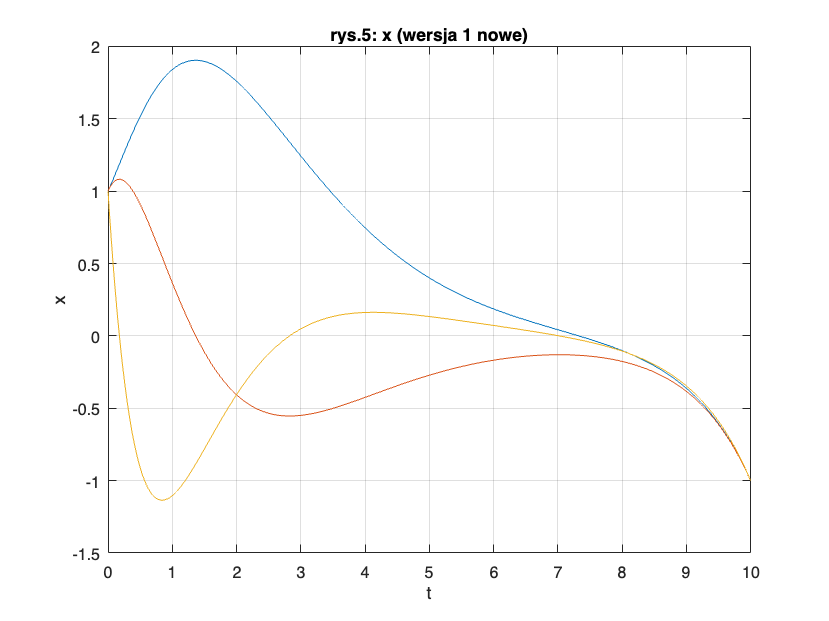

T=0:0.001:t1;
figure(31)
plot(T,x(T))
grid on, xlabel('t'), ylabel('x')
title('rys.5: x (wersja 1 nowe)')


% to samo ale inaczej
% uzyskamy trajektorię x(t), gdzie x(0)=x0 i x(t1)=x1 bazując na tym, że
% układ równań (2,3) będzie reprezentowany przez obiekt klasy ss z Control System
% Toolbox a reakcję na sterowanie (10) wyznaczymy sposobem właściwym dla
% tej klasy
% obiekt klasy ss reprezentujący system (2,3)
systemDynamiczny=ss(A,B,C,D);
u_mf=matlabFunction(u(t))

u_mf = function_handle with value:
    @(t)(t.^2.*exp(t).*(exp(2.0e+1).*1.11e+2-exp(4.0e+1).*9.1e+1).*(-3.85903600725001e+9))./(exp(2.0e+1).*4.9203e+4-exp(4.0e+1).*3.3203e+4+exp(6.0e+1)-1.0)-(t.^2.*exp(t).*(exp(2.0e+1).*-3.62e+2+exp(4.0e+1).*3.2761e+4+1.0).*5.748908572444312e+6)./(exp(2.0e+1).*4.9203e+4-exp(4.0e+1).*3.3203e+4+exp(6.0e+1)-1.0)-(t.^2.*exp(t).*(exp(2.0e+1).*-1.06846e+5+exp(4.0e+1).*4.0843e+4+3.0).*3.986791308859913e+6)./(exp(2.0e+1).*4.9203e+4-exp(4.0e+1).*3.3203e+4+exp(6.0e+1)-1.0)-(exp(t).*(exp(2.0e+1).*1.33e+2-exp(4.0e+1).*7.3e+1).*(t.*4.0+t.^2+2.0).*3.85903600725001e+9)./(exp(2.0e+1).*4.9203e+4-exp(4.0e+1).*3.3203e+4+exp(6.0e+1)-1.0)-(exp(t).*(t.*4.0+t.^2+2.0).*(exp(2.0e+1).*-3.62e+2+exp(4.0e+1).*3.2761e+4+1.0).*3.986791308859913e+6)./(exp(2.0e+1).*4.9203e+4-exp(4.0e+1).*3.3203e+4+exp(6.0e+1)-1.0)-(exp(t).*(t.*4.0+t.^2+2.0).*(exp(2.0e+1).*-8.9086e+4+exp(4.0e+1).*2.6283e+4+3.0).*5.748908572444312e+6)./(exp(2.0e+1).*4.9203e+4-exp(4.0e+1).*3.3203e+4+exp(6.0e+1)-1.0)-(t.*

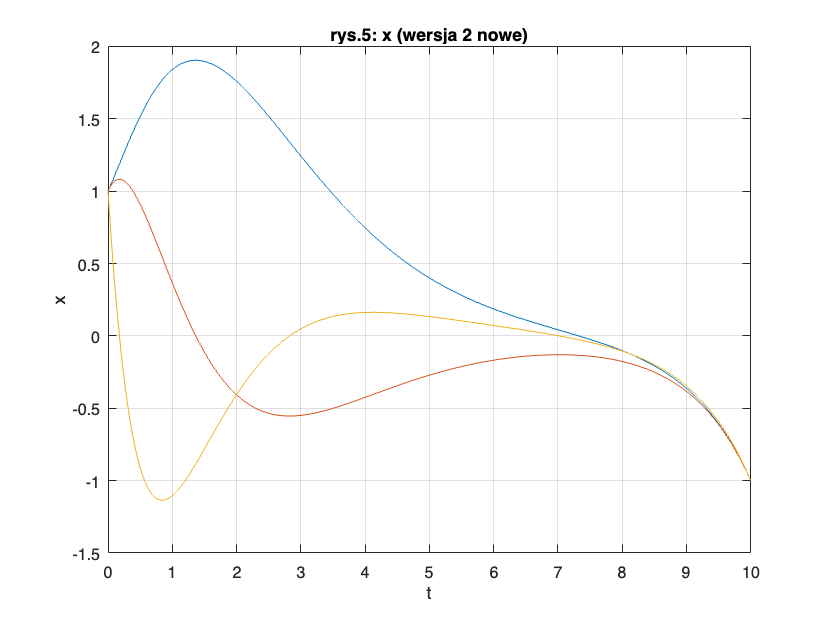

uu=u_mf(T);
% rozwiązanie numeryczne równania (2) dla sterowania (10)
[yy, ttout, xx]=lsim(systemDynamiczny,uu,T,x0);
% tworzenie wykresu dla rozwiązania równania (2) gdzie u ma postać (10)
figure(32)
plot(T,xx)
grid on, xlabel('t'), ylabel('x')
title('rys.5: x (wersja 2 nowe)')

Czy na gruncie uzyskanych wyników dalej możemy przypuszczać, że rozważany system jest sterowalny? Krótko uzasadnić odpowiedź.

**Odpowiedź.** TAK, możemy przupuszczać że system jest sterowalny, ponieważ jesteśmy w stanie doprowadzić go do  stanu x1 ze stanu x0 w zadanym czasie  $t_1=10\mathrm{ [s]}$

## Zadanie 4

Rozważmy system (2), stowarzyszony z nim gramian sterowalności (10) oraz macierz sterowalności Kalmana


$$\Omega=[B ~AB ~A^2B \ldots A^{n-1}B] \quad (12)$$


gdzie $n$ jest wymiarem przestrzeni stanu. Należy zweryfikować na przykładzie, że $\mathrm{rank} ~\Omega = n \Leftrightarrow \mathrm{rank} ~W_{t_1} = n$ ($t_1 >0$).

Niech $A=$$0 \quad -a_0 \brack 1 \quad -a_1
$, $B=$ $b_0 \brack b_1$ gdzie 

- 
$$a_1=3, ~a_0=2, ~b_0=3, ~b_1=1$$
 

- 
$$a_1=3, ~a_0=2, ~b_0=2, ~b_1=1$$


Powyższe zadanie można zrealizować w sposób następujący:

clear all
close all
% deklaracja zmiennych i funkcji symbolicznych (obiektów klasy sym)
syms t u(t) tau X(t) W

% definicje parametrów równania różniczkowego (2)
a2=6;
a1=11;
a0=6;
b2=1;
b1=-3;
b0=2;
A1=[0 0 -a0; 1 0 -a1; 0 1 -a2]

A1 =      0     0    -6
     1     0   -11
     0     1    -6


B1=[b0; b1 ; b2]

B1 =      2
    -3
     1


b1=3;
A2=[0 0 -a0; 1 0 -a1; 0 1 -a2]

A2 =      0     0    -6
     1     0   -11
     0     1    -6


B2=[b0; b1; b2]

B2 =      2
     3
     1



n=size(A1,1)

n = 3

t1=rand*10

t1 = 2.7850


% implementacja gramianu sterowalności (11)
W1=int(expm(-A1*tau)*B1*B1'*expm(-A1'*tau),tau,0,t1)

$$W1 = \begin{array}{l} \left(\begin{array}{ccc} \frac{200\,{\mathrm{e}}^{9406833560347395/562949953421312}}{3}-432\,{\mathrm{e}}^{9406833560347395/1125899906842624}-288\,{\mathrm{e}}^{15678055933912325/1125899906842624}+162\,{\mathrm{e}}^{3135611186782465/562949953421312}+504\,{\mathrm{e}}^{3135611186782465/281474976710656}-\frac{38}{3} & \sigma_{3} & \sigma_{2}\\ \sigma_{3} & 150\,{\mathrm{e}}^{9406833560347395/562949953421312}-480\,{\mathrm{e}}^{9406833560347395/1125899906842624}-576\,{\mathrm{e}}^{15678055933912325/1125899906842624}+\frac{225\,{\mathrm{e}}^{3135611186782465/562949953421312}}{2}+801\,{\mathrm{e}}^{3135611186782465/281474976710656}-\frac{15}{2} & \sigma_{1}\\ \sigma_{2} & \sigma_{1} & \frac{\sigma_{4}}{3}-24\,{\mathrm{e}}^{9406833560347395/1125899906842624}-48\,{\mathrm{e}}^{15678055933912325/1125899906842624}+\frac{9\,{\mathrm{e}}^{3135611186782465/562949953421312}}{2}+51\,{\mathrm{e}}^{3135611186782465/281474976710656}-\frac{1}{6} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sigma_{4}-\sigma_{5}-168\,{\mathrm{e}}^{15678055933912325/1125899906842624}+\frac{45\,{\mathrm{e}}^{3135611186782465/562949953421312}}{2}+204\,{\mathrm{e}}^{3135611186782465/281474976710656}-\frac{1}{2}\\ \sigma_{2}=\frac{\sigma_{6}}{3}-\sigma_{5}-120\,{\mathrm{e}}^{15678055933912325/1125899906842624}+27\,{\mathrm{e}}^{3135611186782465/562949953421312}+168\,{\mathrm{e}}^{3135611186782465/281474976710656}-\frac{1}{3}\\ \sigma_{3}=\sigma_{6}-468\,{\mathrm{e}}^{9406833560347395/1125899906842624}-408\,{\mathrm{e}}^{15678055933912325/1125899906842624}+135\,{\mathrm{e}}^{3135611186782465/562949953421312}+642\,{\mathrm{e}}^{3135611186782465/281474976710656}-1\\ \sigma_{4}=50\,{\mathrm{e}}^{9406833560347395/562949953421312}\\ \sigma_{5}=108\,{\mathrm{e}}^{9406833560347395/1125899906842624}\\ \sigma_{6}=100\,{\mathrm{e}}^{9406833560347395/562949953421312} \end{array}$$

W2=int(expm(-A2*tau)*B2*B2'*expm(-A2'*tau),tau,0,t1)

$$W2 = \begin{array}{l} \left(\begin{array}{ccc} \frac{2\,{\mathrm{e}}^{9406833560347395/562949953421312}}{3}-\frac{2}{3} & {\mathrm{e}}^{9406833560347395/562949953421312}-1 & \sigma_{1}\\ {\mathrm{e}}^{9406833560347395/562949953421312}-1 & \frac{3\,{\mathrm{e}}^{9406833560347395/562949953421312}}{2}-\frac{3}{2} & \sigma_{2}\\ \sigma_{1} & \sigma_{2} & \frac{{\mathrm{e}}^{9406833560347395/562949953421312}}{6}-\frac{1}{6} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{{\mathrm{e}}^{9406833560347395/562949953421312}}{3}-\frac{1}{3}\\ \sigma_{2}=\frac{{\mathrm{e}}^{9406833560347395/562949953421312}}{2}-\frac{1}{2} \end{array}$$

% implementacja macierzy Kalmana (12)
Omega1=[B1 A1*B1 A1^2*B1]

Omega1 =      2    -6    54
    -3    -9    93
     1    -9    45


Omega2=[B2 A2*B2 A2^2*B2]

Omega2 =      2    -6    18
     3    -9    27
     1    -3     9



if rank(W1)==n && rank(Omega1)==n
    disp(':)');
else
    disp(':(');
end

:)



if rank(W2)==n && rank(Omega2)==n
    disp(':)');
else
    disp(':(');
end

:(



if rank(W1)~=n && rank(Omega1)~=n
    disp(':)');
else
    disp(':(');
end

:(



if rank(W2)~=n && rank(Omega2)~=n
    disp(':)');
else
    disp(':(');
end

:)


Wykonać powyższą analizę dla przypadku gdy $A=$$\left\lbrack \begin{array}{ccc}
0 & 0 & -a_0 \\
1 & 0 & -a_1 \\
0 & 1 & -a_2 
\end{array}\right\rbrack$, $B=$$\left\lbrack \begin{array}{c}
b_0 \\
b_1 \\
b_2 
\end{array}\right\rbrack$, oraz

- 
$$a_2=6, ~a_1=11, ~a_0=6, ~b_2=1, ~b_1=3, ~b_0=2$$


- 
$$a_2=6, ~a_1=11, ~a_0=6, ~b_2=1, ~b_1=-3, ~b_0=2$$


Czy uzyskaliśmy podobny wynik jak we wcześniejszym przypadku, w szczególności czy możemy dalej przypuszczać, że $\mathrm{rank} ~\Omega = n \Leftrightarrow \mathrm{rank} ~W_{t_1} = n$. Uzasadnij krótko swoją odpowiedź.

**Odpowiedź.** Dla pierwszego zestawu danych warunek $\mathrm{rank} ~\Omega = n \Leftrightarrow \mathrm{rank} ~W_{t_1} = n$ nie jest spełniony, dla drugiego rząd macierzy W i Q są równe wymiarowi przestrzeni stanu n, co świadczy o tym, że układ jest sterowalny. Zatem wystarczy sprawdzić  rząd W lub rząd Q, aby ocenić, czy układ jest sterowalny. Jeśli  w jednej z tych macierzy rząd jest mniejszy niż n, układ nie jest sterowalny. Jeśli w obu rzędy są równe n układ jest sterowalny.